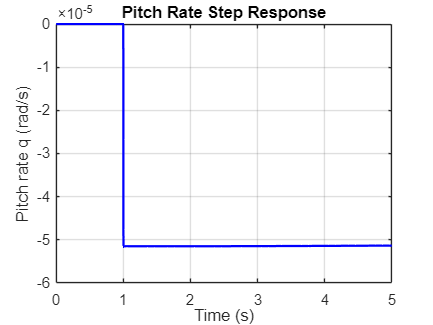

clear
clc


% 0 Controller value

Kp_1 = 97;

% 1 Run model
open('Pitch_Rate_Damper.slx')
out = sim('Pitch_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.q.Time;      % Time vector
q = out.q.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, q, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch rate q (rad/s)');
title('Pitch Rate Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(q, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0013
    TransientTime: 1.0024
     SettlingTime: 1.0024
      SettlingMin: -5.1579e-05
      SettlingMax: -4.7559e-05
        Overshoot: 0.4783
       Undershoot: 0
             Peak: 5.1579e-05
         PeakTime: 1.0061

